# NR FDD Scheduling Performance Evaluation

This example shows scheduling in frequency division duplexing (FDD) mode with medium access control (MAC) logical channel prioritization (LCP) functionality and evaluates the network performance. Scheduling strategy controls the downlink (DL) and uplink (UL) scheduling of resources and can be customized to evaluate the performance. The example shows the functionality of the radio link control (RLC) layer in unacknowledged mode (UM) with LCP to serve multiple logical channels. You can model different application traffic patterns. A passthrough physical (PHY) layer without any physical layer processing is used, which adopts a probability-based approach to model packet reception failures. You can switch to 5G Toolbox™ based PHY layer for high fidelity physical layer processing. The performance of the scheduling strategy is evaluated in terms of achieved throughput and the fairness in resource sharing.

## Introduction

This example shows how a scheduling strategy (controlled by the gNB) assigns UL and DL resources among the UEs. The example considers the following operations within the gNB and UEs that facilitate UL and DL transmissions and receptions.

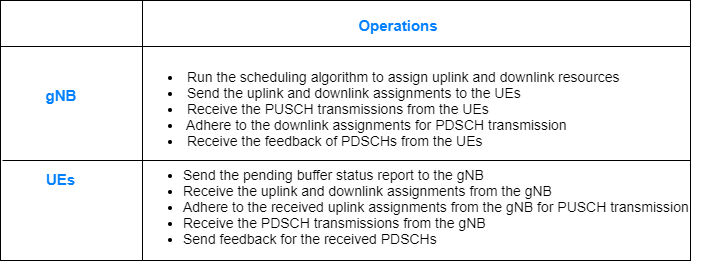

The complete PUSCH or PDSCH packet is transmitted in the first symbol of its allocated symbol set. Receiver processes the packet in the symbol just after the last symbol in the allocated symbol set.

The schedulers (UL and DL) run every *p* slots to assign the UL and DL resources, where *p* is the configured periodicity of the scheduler. In each run, the number of slots scheduled is equal to the periodicity of scheduler run, *p*.

**UL Scheduler**

The first slot, among the *p* slots to be scheduled in a run, is the nearest upcoming slot which satisfies the PUSCH preparation time capability of UEs. For example, the figure shows the way scheduler selects the slots during two consecutive runs. It assumes scheduler periodicity (*p)* as 3 slots. Hence, the scheduler runs after every 3 slots, and schedules resources for 3 slots. PUSCH preparation time capability for all the UEs is assumed as greater than 1 slot (14 symbols) but less than 2 slots (28 symbols).

- Run-1: When scheduler runs at the start of Slot-A, it schedules 3 slots starting from Slot-C, because for Slot-A and Slot-B the UEs do not get enough PUSCH preparation time (UEs gets a time of 0 symbols at start of Slot-A and 14 symbols at start of Slot-B). For Slot-C, UEs get 28 symbols for PUSCH preparation and this satisfies the PUSCH preparation time capability. Hence, Slot-C, D, and E are scheduled in this run.

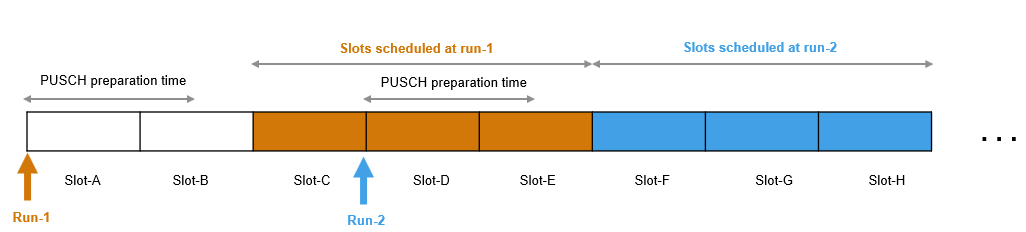

- Run-2: When scheduler runs at the start of Slot-D, it schedules the next 3 contiguous slots starting from Slot-F (Slot-F, G, and H).

**DL Scheduler**

The first slot, among the *p* slots to be scheduled in a run, is the immediate next slot.

- Run-1: When scheduler runs at the start of Slot-A, it schedules 3 contiguous slots Slot-B, C, and D.

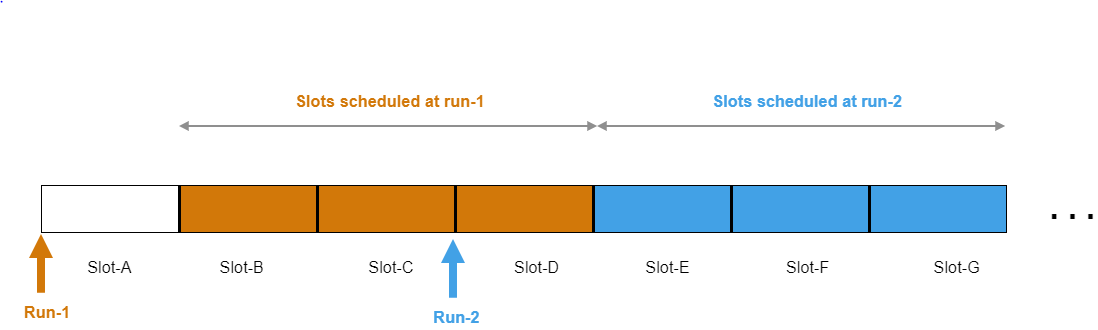

- Run-2: When scheduler runs at the start of Slot-D, it schedules 3 contiguous slots Slot-E, F, and G.

You can choose any one of the implemented scheduling strategies: proportional fair (PF), best CQI, or round robin (RR). The various supported inputs to the UL scheduler are listed along with the scheduling strategies that consider them.

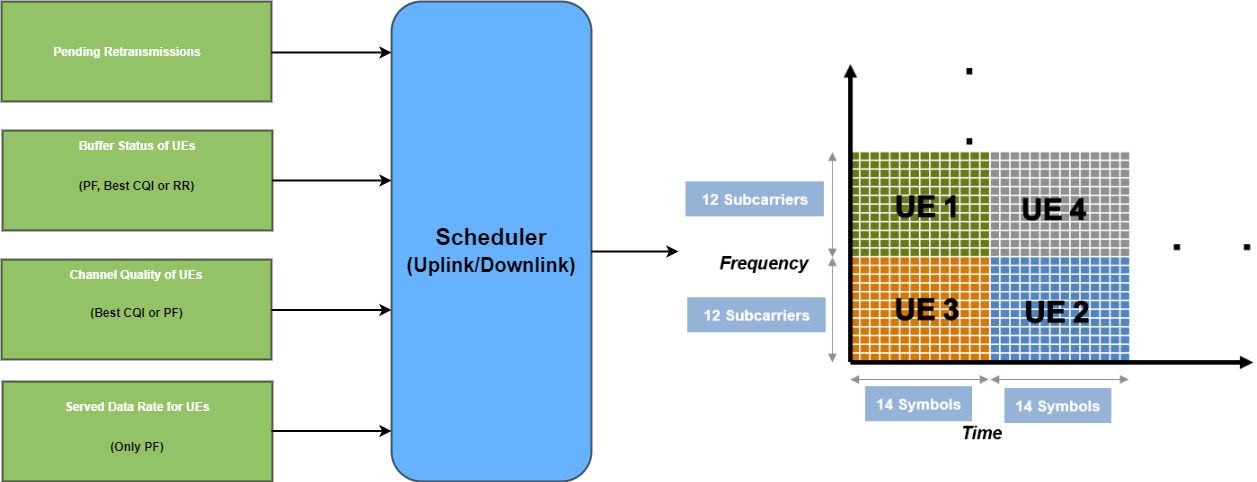

The control packets required are assumed to be sent out of band without the need of resources for transmission. The control packets are UL assignment, DL assignment, buffer status report (BSR), and PDSCH feedback.

The demodulation reference signal (DM-RS) is not modeled in this example. However, one symbol is kept unused for it in the PUSCH and PDSCH assignments.

This example models:

- Slot-based UL and DL scheduling. The time-domain granularity of the UL assignment and DL assignment is one slot.

- Noncontiguous allocation of frequency-domain resources in terms of resource block groups (RBGs).

- Configurable subcarrier spacing resulting in different slot durations.

- Asynchronous adaptive hybrid automatic repeat request (HARQ) mechanism in UL and DL.

- Multiple logical channels to support different kind of applications.

- Logical channel prioritization (LCP) to distribute the received assignment among logical channels per UE for UL and DL.

## Scenario Configuration

Set the parameters for simulation.

rng('default'); % Reset the random number generator
simParameters = []; % Clear the simulation parameters

simParameters.NumFramesSim = 100; % Simulation time in terms of number of 10 ms frames
% Number of UEs in the simulation. UEs are assumed to have sequential radio
% network temporary identifiers (RNTIs) from 1 to NumUEs. If you change the
% number of UEs, ensure that the length of simParameters.UEDistance is equal to NumUEs
simParameters.NumUEs = 4;
simParameters.UEDistance = [100 250 700 750]; % Distance of UEs from gNB (in meters)

% Set the channel bandwidth to 30 MHz and subcarrier spacing (SCS) to 15
% kHz as defined in 3GPP TS 38.104 Section 5.3.2. The complete UL and
% DL bandwidth is assumed to be allotted for PUSCH and PDSCH. The
% UL and DL carriers are assumed to have symmetric channel
% bandwidth
simParameters.DLBandwidth = 30e6; % Hz
simParameters.ULBandwidth = 30e6; % Hz
simParameters.NumRBs = 160;
simParameters.SCS = 15; % kHz
simParameters.DLCarrierFreq = 2.635e9; % Hz
simParameters.ULCarrierFreq = 2.515e9; % Hz

% Configure parameters to update UL channel quality at gNB and DL
% channel quality at gNB and UE. Channel conditions are periodically
% improved or deteriorated by CQIDelta every channelUpdatePeriodicity
% seconds for all RBs of a UE. Whether channel conditions for a particular
% UE improve or deteriorate is randomly determined
% RBCQI = RBCQI +/- CQIDelta
simParameters.ChannelUpdatePeriodicity = 0.2; % In sec
simParameters.CQIDelta = 2;
% Mapping between distance from gNB (first column in meters) and maximum
% achievable UL CQI value (second column). For example, if a UE is 700
% meters away from the gNB, it can achieve a maximum CQI value of 10 as the
% distance falls within the [501, 800] meters range, as per the mapping.
% Set the distance in increasing order and the maximum achievable CQI value in
% decreasing order
simParameters.CQIvsDistance = [
    200  15;
    500  12;
    800  10;
    1000  8;
    1200  7];

simParameters.BSRPeriodicity = 5; % In ms
simParameters.EnableHARQ = true; % Flag to enable or disable HARQ. If disabled, there are no retransmissions
simParameters.NumHARQ = 16; % Number of HARQ processes

% Set the scheduler run periodicity in terms of number of slots. Value must
% be less than the number of slots in a 10 ms frame
simParameters.SchedulerPeriodicity = 4;
simParameters.SchedulerStrategy = 'PF'; % Supported scheduling strategies: 'PF', 'RR' and 'BestCQI'
% Moving average parameter within the range [0, 1] to calculate average
% data rate for a UE in UL and DL directions. This value is used in
% the PF scheduling strategy. Parameter value closer to 1 implies more
% weight on the instantaneous data rate. Parameter value closer to 0
% implies more weight on the past data rate
% AverageDataRate = ((1 - MovingAvgDataRateWeight) * PastDataRate) + (MovingAvgDataRateWeight * InstantaneousDataRate)
simParameters.MovingAvgDataRateWeight = 0.5;
% gNB ensures that PUSCH assignment is received at UEs PUSCHPrepTime ahead
% of the transmission time
simParameters.PUSCHPrepTime = 200; % In microseconds
% Maximum RBs allotted to a UE in a slot for the UL and DL
% transmission (limit is applicable for new PUSCH and PDSCH assignments and
% not for the retransmissions)
simParameters.RBAllocationLimitUL = 100; % For PUSCH
simParameters.RBAllocationLimitDL = 100; % For PDSCH

Load the logical channel configuration table. Each row in the table represents one logical channel and has these properties as columns.

- RNTI - Radio network temporary identifier of the UE.

- LogicalChannelID - Logical channel identifier.

- LCGID - Logical channel group identifier.

- SeqNumFieldLength - Defines the sequence number field length. It takes either 6 or 12.

- MaxTxBufferSDUs - Maximum Tx buffer size (in terms of number of packets).

- ReassemblyTimer - Defines the reassembly timer (in ms).

- EntityType - Defines the RLC entity type. It takes values 0, 1, and 2, which indicates whether the RLC UM entity is unidirectional DL, unidirectional UL, or bidirectional UM, respectively.

- Priority - Priority of the logical channel.

- PBR - Prioritized bit rate (in kilo bytes per second).

- BSD - Bucket size duration (in ms).

load('NRFDDRLCChannelConfig.mat')
simParameters.RLCChannelConfig = RLCChannelConfig;

Load the application configuration table containing these fields. Each row in the table represents one application and has these properties as columns.

- PacketInterval - Interval between two consecutive packet generations (in ms).

- PacketSize - Size of the packet (in bytes).

- HostDevice - Defines the device (UE or gNB) on which the application is installed with the specified configuration. The device takes values 0, 1, or 2. The values indicate the application is configured on gNB side, UE side, or both UE and gNB respectively.

- RNTI - Radio network temporary identifier of a UE. This identifies the UE for which the application is installed.

- LCID - Logical channel identifier.

load('NRFDDAppConfig.mat');
simParameters.AppConfig = AppConfig;

Logging and Visualization Configuration

% The parameters CQIVisualization and RBVisualization control the display
% of these visualizations: (i) CQI visualization of RBs (ii) RB assignment
% visualization. By default, these plots are disabled. You can enable them
% by setting to 'true'
simParameters.CQIVisualization = false;
simParameters.RBVisualization = false;
% The output metrics plots are updated periodically NumMetricsSteps times within the
% simulation duration
simParameters.NumMetricsSteps = 20;
% MAT-files to write the logs into. They are used for post simulation analysis and visualization
simParameters.ParametersLogFile = 'simParameters'; % For logging the simulation parameters
simParameters.SimulationLogFile = 'simulationLogs'; % For logging the simulation logs

% Validate the simulation configuration
hNRSchedulingFDDValidateConfig(simParameters);

## Derived Parameters

Based on the primary configuration parameters, compute the derived parameters. Additionally, set some example specific constants.

simParameters.DuplexMode = 0; % FDD
% Size of sub-band for CQI reporting in terms of number of RBs (Only used
% when 5G Toolbox™ PHY layer processing is enabled)
simParameters.SubbandSize = 16;
simParameters.NumCells = 1; % Number of cells
simParameters.NCellID = 1; % Physical cell ID
simParameters.GNBPosition = [0 0 0]; % Position of gNB in (x,y,z) coordinates
% Slot duration for the selected SCS and number of slots in a 10 ms frame
slotDuration = 1/(simParameters.SCS/15); % In ms
numSlotsFrame = 10/slotDuration; % Number of slots in a 10 ms frame
numSlotsSim = simParameters.NumFramesSim * numSlotsFrame; % Number of slots in the simulation

% Calculate maximum achievable CQI value for the UEs based on their distance from
% the gNB
maxUECQIs = zeros(simParameters.NumUEs, 1); % To store the maximum achievable CQI value for UEs
for ueIdx = 1:simParameters.NumUEs
    % Based on the distance of the UE from gNB, find matching row in
    % CQIvsDistance mapping
    matchingRowIdx = find(simParameters.CQIvsDistance(:, 1) > simParameters.UEDistance(ueIdx));
    if isempty(matchingRowIdx)
        maxUECQIs(ueIdx) = simParameters.CQIvsDistance(end, 2);
    else
        maxUECQIs(ueIdx) = simParameters.CQIvsDistance(matchingRowIdx(1), 2);
    end
end

% Interval at which metrics visualization updates in terms of number of
% slots. As one slot is the finest time-granularity of the simulation, make
% sure that MetricsStepSize is an integer
simParameters.MetricsStepSize = ceil(numSlotsSim / simParameters.NumMetricsSteps);
if mod(numSlotsSim, simParameters.NumMetricsSteps) ~= 0
    % Update the NumMetricsSteps parameter if NumSlotsSim is not
    % completely divisible by it
    simParameters.NumMetricsSteps = floor(numSlotsSim / simParameters.MetricsStepSize);
end

% Define initial UL and DL channel quality as an N-by-P matrix,
% where 'N' is the number of UEs and 'P' is the number of RBs in the carrier
% bandwidth. The initial value of CQI for each RB, for each UE, is given
% randomly and is limited by the maximum achievable CQI value corresponding
% to the distance of the UE from gNB
simParameters.InitialChannelQualityUL = zeros(simParameters.NumUEs, simParameters.NumRBs); % To store current UL CQI values on the RBs for different UEs
simParameters.InitialChannelQualityDL = zeros(simParameters.NumUEs, simParameters.NumRBs); % To store current DL CQI values on the RBs for different UEs
for ueIdx = 1:simParameters.NumUEs
    % Assign random CQI values for the RBs, limited by the maximum achievable CQI value
    simParameters.InitialChannelQualityUL(ueIdx, :) = randi([1 maxUECQIs(ueIdx)], 1, simParameters.NumRBs);
    % Initially, DL and UL CQI values are assumed to be equal
    simParameters.InitialChannelQualityDL(ueIdx, :) = simParameters.InitialChannelQualityUL(ueIdx, :);
end

## gNB and UEs Setup

Create the gNB and UE objects, initialize the channel quality information for UEs, and set up the logical channel at gNB and UE. The helper classes [hNRGNB.m](matlab:edit('hNRGNB')) and [hNRUE.m](matlab:edit('hNRUE')) create gNB and UE nodes respectively, containing the RLC and MAC layers. For MAC layer, [hNRGNB.m](matlab:edit('hNRGNB')) uses the helper class [hNRGNBMAC.m](matlab:edit('hNRGNBMAC')) to implement the gNB MAC functionality and  [hNRUE.m](matlab:edit('hNRUE')) uses [hNRUEMAC.m](matlab:edit('hNRUEMAC')) to implement the UE MAC functionality. Schedulers are implemented in [hNRSchedulerRoundRobin.m](matlab:edit('hNRSchedulerRoundRobin')) (RR), [hNRSchedulerProportionalFair.m](matlab:edit('hNRSchedulerProportionalFair')) (PF), [hNRSchedulerBestCQI.m](matlab:edit('hNRSchedulerBestCQI')) (Best CQI) . All the schedulers inherit from the base class [hNRScheduler.m](matlab:edit('hNRScheduler')) which contains the core scheduling functionality. For RLC layer, both [hNRGNB.m](matlab:edit('hNRGNB')) and [hNRUE.m](matlab:edit('hNRUE')) use [hNRUMEntity.m](matlab:edit('hNRUMEntity')) to implement the functionality of the RLC transmitter and receiver. Passthrough PHY layer for UE and gNB is implemented in [hNRUEPassThroughPhy.m](matlab:edit('hNRUEPassThroughPhy')) and [hNRGNBPassThroughPhy.m](matlab:edit('hNRGNBPassThroughPhy')), respectively.

simParameters.Position = simParameters.GNBPosition;
gNB = hNRGNB(simParameters); % Create gNB node

% Create and add scheduler
switch(simParameters.SchedulerStrategy)
    case 'RR' % Round robin scheduler
        scheduler = hNRSchedulerRoundRobin(simParameters);
    case 'PF' % Proportional fair scheduler
        scheduler = hNRSchedulerProportionalFair(simParameters);
    case 'BestCQI' % Best CQI scheduler
        scheduler = hNRSchedulerBestCQI(simParameters);
end
addScheduler(gNB, scheduler); % Add scheduler to gNB

gNB.PhyEntity = hNRGNBPassThroughPhy(simParameters); % Add passthrough PHY
configurePhy(gNB, simParameters);
setPhyInterface(gNB); % Set the interface to PHY layer

% Create the set of UE nodes
UEs = cell(simParameters.NumUEs, 1); 
for ueIdx=1:simParameters.NumUEs
    simParameters.Position = [simParameters.UEDistance(ueIdx) 0 0]; % Position of UE
    UEs{ueIdx} = hNRUE(simParameters, ueIdx);
    UEs{ueIdx}.PhyEntity = hNRUEPassThroughPhy(simParameters, ueIdx); % Add passthrough PHY
    configurePhy(UEs{ueIdx}, simParameters);
    setPhyInterface(UEs{ueIdx}); % Set the interface to PHY layer
    
    % Initialize the UL CQI values at gNB
    updateChannelQuality(gNB, simParameters.InitialChannelQualityUL(ueIdx, :), 1, ueIdx); % 1 for UL
    % Initialize the DL CQI values at gNB and UE. The DL CQI values
    % help gNB in scheduling, and UE in packet error probability estimation
    updateChannelQuality(gNB, simParameters.InitialChannelQualityDL(ueIdx, :), 0, ueIdx); % 0 for DL
    updateChannelQuality(UEs{ueIdx}, simParameters.InitialChannelQualityDL(ueIdx, :));
end

% Setup logical channels
for lchInfoIdx = 1:size(simParameters.RLCChannelConfig, 1)
    rlcChannelConfigStruct = table2struct(simParameters.RLCChannelConfig(lchInfoIdx, :));
    ueIdx = simParameters.RLCChannelConfig.RNTI(lchInfoIdx);
    % Setup the logical channel at gNB and UE
    gNB.configureLogicalChannel(ueIdx, rlcChannelConfigStruct);
    UEs{ueIdx}.configureLogicalChannel(ueIdx, rlcChannelConfigStruct);
end

% Add data traffic pattern generators to gNB and UE nodes
for appIdx = 1:size(simParameters.AppConfig, 1)
    device = simParameters.AppConfig.HostDevice(appIdx);
    rnti = simParameters.AppConfig.RNTI(appIdx);
    lcid = simParameters.AppConfig.LCID(appIdx);
    packetSize = simParameters.AppConfig.PacketSize(appIdx);
    packetInterval = simParameters.AppConfig.PacketInterval(appIdx);
    % Calculate the data rate (in kbps) of On-Off traffic pattern using
    % packet size (in bytes) and packet interval (in ms)
    dataRate = ceil(1000/packetInterval) * packetSize * 8e-3;
    % Limit the size of the generated application packet to the maximum RLC
    % SDU size. The maximum supported RLC SDU size is 9000 bytes
    if packetSize > 9000
        packetSize = 9000;
    end
    % Create an object for On-Off network traffic pattern and add it to the
    % specified UE. This object generates the uplink data traffic on the UE
    if device == 1 || device == 2
        ulApp = networkTrafficOnOff('PacketSize', packetSize, 'GeneratePacket', true, ...
            'OnTime', simParameters.NumFramesSim/100, 'OffTime', 0, 'DataRate', dataRate);
        UEs{rnti}.addApplication(rnti, lcid, ulApp);
    end
    % Create an object for On-Off network traffic pattern for the specified
    % UE and add it to the gNB. This object generates the downlink data
    % traffic on the gNB for the UE
    if device == 0 || device == 2
        dlApp = networkTrafficOnOff('PacketSize', packetSize, 'GeneratePacket', true, ...
            'OnTime', simParameters.NumFramesSim/100, 'OffTime', 0, 'DataRate', dataRate);
        gNB.addApplication(rnti, lcid, dlApp);
    end
end

% Setup the UL and DL packet distribution mechanism
simParameters.MaxReceivers = simParameters.NumUEs;
% Create DL packet distribution object
dlPacketDistributionObj = hNRPacketDistribution(simParameters, 0); % 0 for DL
% Create UL packet distribution object
ulPacketDistributionObj = hNRPacketDistribution(simParameters, 1); % 1 for UL
hNRSetUpPacketDistribution(simParameters, gNB, UEs, dlPacketDistributionObj, ulPacketDistributionObj);

## Processing Loop

Simulation is run slot by slot. In each slot, these operations are executed:

- Run the MAC and PHY layers of gNB

- Run the MAC and PHY layers of UEs

- Layer specific logging and visualization 

- Advance the timer for the nodes. Every 1 ms it also sends trigger to application and RLC layers. Application layer and RLC layer execute their scheduled operations based on 1 ms timer trigger.

% To store these UE metrics for each slot: throughput bytes
% transmitted, goodput bytes transmitted, and pending buffer amount bytes.
% The number of goodput bytes is calculated by excluding the
% retransmissions from the total transmissions
UESlotMetricsUL = zeros(simParameters.NumUEs, 3);
UESlotMetricsDL = zeros(simParameters.NumUEs, 3);

% To store the RLC statistics for each slot
ueRLCStats = cell(simParameters.NumUEs, 1);
gNBRLCStats = cell(simParameters.NumUEs, 1);

 % To store current UL and DL CQI values on the RBs for different UEs
uplinkChannelQuality = zeros(simParameters.NumUEs, simParameters.NumRBs);
downlinkChannelQuality = zeros(simParameters.NumUEs, simParameters.NumRBs);

 % To store last received UL and DL HARQ process NDI flag value at UE
HARQProcessStatusUL = zeros(simParameters.NumUEs, simParameters.NumHARQ);
HARQProcessStatusDL = zeros(simParameters.NumUEs, simParameters.NumHARQ);

% Create an object for MAC (UL & DL) scheduling information visualization and logging
simSchedulingLogger = hNRSchedulingLogger(simParameters);

% To store the logical channel information associated per UE
lchInfo = repmat(struct('LCID',[],'EntityDir',[]), [simParameters.NumUEs 1]);
for ueIdx = 1:simParameters.NumUEs
    lchInfo(ueIdx).LCID = simParameters.RLCChannelConfig.LogicalChannelID(simParameters.AppConfig.RNTI == ueIdx);
    lchInfo(ueIdx).EntityDir = simParameters.RLCChannelConfig.EntityType(simParameters.AppConfig.RNTI == ueIdx);
end

% Create an object for RLC visualization and logging
simRLCLogger = hNRRLCLogger(simParameters, lchInfo);

symbolNum = 0;
% Run processing loop
for slotNum = 1:numSlotsSim
    
    % Run MAC and PHY layers of gNB
    run(gNB.MACEntity);
    run(gNB.PhyEntity);
    
    % Run MAC and PHY layers of UEs
    for ueIdx = 1:simParameters.NumUEs
        % Read the last received NDI flags for HARQ processes for
        % logging (Reading it before it gets overwritten by run function of MAC)
        HARQProcessStatusUL(ueIdx, :) = getLastNDIFlagHarq(UEs{ueIdx}.MACEntity, 1); % 1 for UL
        HARQProcessStatusDL(ueIdx, :) = getLastNDIFlagHarq(UEs{ueIdx}.MACEntity, 0); % 0 for DL
        run(UEs{ueIdx}.MACEntity); 
        run(UEs{ueIdx}.PhyEntity);
    end
    
    % RLC logging
    for ueIdx = 1:simParameters.NumUEs % For all UEs
        % Get RLC statistics
        ueRLCStats{ueIdx} = getRLCStatistics(UEs{ueIdx}, ueIdx);
        gNBRLCStats{ueIdx} = getRLCStatistics(gNB, ueIdx);
    end
    logRLCStats(simRLCLogger, ueRLCStats, gNBRLCStats); % Update RLC statistics logs
    
    % MAC logging
    % Read UL and DL assignments done by gNB MAC scheduler
    % at current time. Resource assignments returned by a scheduler (either
    % UL or DL) is empty, if either scheduler was not scheduled to run at
    % the current time or no resources got scheduled
    [resourceAssignmentsUL, resourceAssignmentsDL] = getCurrentSchedulingAssignments(gNB.MACEntity);
    % Read throughput and goodput bytes sent for each UE
    [UESlotMetricsDL(:, 1), UESlotMetricsDL(:, 2)] = getTTIBytes(gNB);
    UESlotMetricsDL(:, 3) = getBufferStatus(gNB); % Read pending buffer (in bytes) on gNB
    for ueIdx = 1:simParameters.NumUEs
        % Read the UL channel quality at gNB for each of the UEs for logging
        uplinkChannelQuality(ueIdx,:) = getChannelQuality(gNB, 1, ueIdx); % 1 for UL
        % Read the DL channel quality at gNB for each of the UEs for logging
        downlinkChannelQuality(ueIdx,:) = getChannelQuality(gNB, 0, ueIdx); % 0 for DL
        % Read throughput and goodput bytes transmitted for this UE in the current TTI for logging
        [UESlotMetricsUL(ueIdx, 1), UESlotMetricsUL(ueIdx, 2)] = getTTIBytes(UEs{ueIdx});
        UESlotMetricsUL(ueIdx, 3) = getBufferStatus(UEs{ueIdx}); % Read pending buffer (in bytes) on UE
    end
    % Update scheduling logs based on the current slot run of UEs and gNB.
    % Logs are updated in each slot, RB grid visualizations are updated
    % every frame, and metrics plots are updated every metricsStepSize
    % slots
    logScheduling(simSchedulingLogger, symbolNum + 1, resourceAssignmentsUL, UESlotMetricsUL, uplinkChannelQuality, HARQProcessStatusUL, 1); % 1 for UL
    logScheduling(simSchedulingLogger, symbolNum + 1, resourceAssignmentsDL, UESlotMetricsDL, downlinkChannelQuality, HARQProcessStatusDL, 0); % 0 for DL

    % Visualization
    % RB assignment visualization (if enabled)
    if simParameters.RBVisualization
        if mod(slotNum, numSlotsFrame) == 0
            plotRBGrids(simSchedulingLogger);
        end
    end
    % CQI grid visualization (if enabled)
    if simParameters.CQIVisualization
        if mod(slotNum, numSlotsFrame) == 0
            plotCQIRBGrids(simSchedulingLogger);
        end
    end
    % Plot scheduler metrics and RLC metrics visualization at slot
    % boundary, if the update periodicity is reached
    if mod(slotNum, simParameters.MetricsStepSize) == 0
        plotMetrics(simSchedulingLogger);
        plotMetrics(simRLCLogger);
    end

    % Advance timer ticks for gNB and UEs by the number of symbols per slot
    advanceTimer(gNB, 14);
    for ueIdx = 1:simParameters.NumUEs
        advanceTimer(UEs{ueIdx}, 14);
    end

    % Symbol number in the simulation
    symbolNum = symbolNum + 14; 
end

## Simulation Visualization

The five types of run-time visualization shown are:

- *Display of CQI values for UEs over the PUSCH and PDSCH bandwidth*: You can enable this visualization in the Logging and Visualization Configuration section. For details, see the 'Channel Quality Visualization' figure description in [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3) example.

- *Display of resource grid assignment to UEs*: The 2D time-frequency grid shows the resource allocation to the UEs. You can enable this visualization in the Logging and Visualization Configuration section. For details, see the 'Resource Grid Allocation' figure in [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3) example.

- *Display of UL scheduling metrics plots*: The four plots displayed in 'Uplink Scheduler Performance Metrics' figure represent: UL throughput (per UE and cell), UL goodput (per UE and cell), resource share percentage among UEs (out of the total UL resources) to convey the fairness of scheduling, and pending UL buffer-status of UEs to show whether UEs are getting sufficient resources. The maximum achievable data rate value for UL throughput is shown with a dashed line in throughput and goodput plots. The performance metrics plots update for every `metricsStepSize` slots.

- *Display of DL scheduling metrics plots*: Like UL metrics plots, 'Downlink Scheduler Performance Metrics' displays corresponding subplots for DL direction. The performance metrics plots update for every `metricsStepSize` slots.

- *Display of RLC metrics plots*: The 'RLC Throughput Visualization' figure shows the throughput of the RLC logical channel for the selected UE. The RLC metrics plot update for every `metricsStepSize` slots.

## Simulation Logs

The parameters used for simulation and the simulation logs are saved in MAT-files for post simulation analysis and visualization. The simulation parameters are saved in a MAT-file with the file name as the value of configuration parameter `simParameters.ParametersLogFile`. The per time step logs, scheduling assignment logs, and RLC logs are saved in the MAT-file `simParameters.SimulationLogFile`. After the simulation, open the file to load `DLTimeStepLogs`, `ULTimeStepLogs` `SchedulingAssignmentLogs`, and `RLCLogs` in the workspace.

**Time step logs:** Both the DL and UL time step logs follow the same format. For details of log format, see the 'Simulation Logs' section of [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3).

**Scheduling assignment logs:** Information of all the scheduling assignments and the related information is logged in this file. The table shows sample log entries.

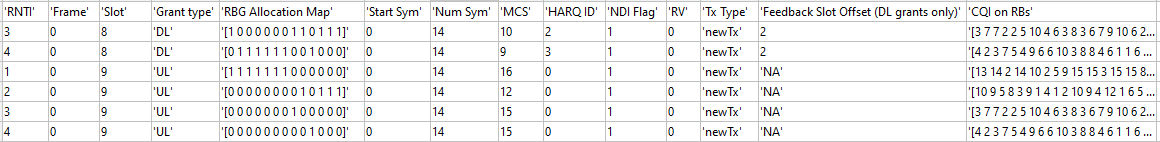

**RLC logs:** For more information on the RLC log format, see [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3).

You can run the script [NRPostSimVisualization](matlab:edit('NRPostSimVisualization.m')) to get a post simulation visualization of logs. In the post simulation script, you are provided with variable `isLogReplay`, which provides these options to visualize 'Resource Grid Allocation' and 'Channel Quality Visualization' figures.

- Set `isLogReplay` to true for replay of simulation logs.

- Set `isLogReplay` to false to analyze the details of a particular frame. In the 'Resource Grid Allocation' window, input the frame number to visualize the resource assignment for the entire frame. The frame number entered here controls the frame number for the 'Channel Quality Visualization' figure too.

% Get the logs
simulationLogs = cell(1,1);
logInfo = struct('DLTimeStepLogs',[], 'ULTimeStepLogs',[], 'SchedulingAssignmentLogs',[] ,'RLCLogs',[]);
[logInfo.DLTimeStepLogs, logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger); % Scheduling assignments log
logInfo.RLCLogs = getRLCLogs(simRLCLogger);
simulationLogs{1} = logInfo;
save(simParameters.ParametersLogFile, 'simParameters'); % Save simulation parameters in a MAT-file
save(simParameters.SimulationLogFile, 'simulationLogs'); % Save simulation logs in a MAT-file

## Further Exploration

You can use this example to further explore these options.

### Custom scheduling

You can modify the existing scheduling strategy to implement a custom one. Peform following steps to accomplish this.

**Create a custom scheduler class**

Create a new class `customStrategy.m` and inherit from [hNRScheduler.m](matlab:edit('hNRScheduler')). Implement the constructor of the class to call the base class constructor as shown below. See the constuctor of [hNRSchedulerRoundRobin.m](matlab:edit('hNRSchedulerRoundRobin')), [hNRSchedulerProportionalFair.m](matlab:edit('hNRSchedulerProportionalFair')), [hNRSchedulerBestCQI.m](matlab:edit('hNRSchedulerBestCQI')) for more details.

**Implement custom UL scheduling**

Override the `scheduleULResourcesSlot` function of the base class by implementing it in the class `customStrategy.m`. function.

First input `obj` is the custom scheduler object. By virtue of inheritance, it contains the context of base class [hNRScheduler.m](matlab:edit('hNRScheduler')) which can be used as input for taking scheduling decisions. Second input `slotNum` is the slot number in the 10 ms frame whose UL resources are getting scheduled. Note that it is not the current slot in which UL scheduler is running but the slot which is getting scheduled. Using the context in `obj`, do the custom scheduling and populate the output `uplinkGrants` of this function with an array of valid UL scheduling assignments. `uplinkGrants` can have maximum one assignment per UE. Each element in this array is PUSCH assignment for a UE. Also, update the context of UL HARQ processes as per the HARQ process ID assigned in the UL assignments. See the `scheduleULResourcesSlot` function in [hNRScheduler.m](matlab:edit('hNRScheduler')) for more details.

**Implement custom DL scheduling**

Follow the procedure like custom UL scheduling to override the `scheduleDLResourcesSlot` function of the base class by implementing it in the class `customStrategy.m`. function.

**Create and install the custom scheduler**

To use the custom scheduler in this example, create its object and install it on the gNB in the gNB and UEs Setup section.

### Use 5G Toolbox™ physical layer

You can also switch from passthrough PHY layer to 5G Toolbox™ physical layer processing by creating PHY objects using [hNRGNBPhy.m](matlab:edit('hNRGNBPhy.m')) and [hNRUEPhy.m](matlab:edit('hNRUEPhy.m')). For more details, see 'gNB and UEs Setup' section of [NR Cell Performance Evaluation with Physical Layer Integration](docid:5g_ug#mw_c54c277c-b9c5-4626-b12b-a5db59672570).

Based on the chosen scheduling strategy, this example shows the assignment of UL and DL resources to multiple UEs by the gNB. A run-time visualization display of the resource grid gives detailed information about the RBs allocated to each UE and the HARQ process ID assigned for transmission. UL and DL scheduling performance is analyzed based on run-time plots of throughput and goodput, resource share fairness, and pending buffer status on the UEs. A more thorough post simulation analysis by using the saved logs gives a detailed picture of the operations happening on a per slot basis.

### Use RLC AM

You can also switch the operating mode of an RLC entity from UM to acknowledged mode (AM) by modifying the input structure fields `EntityType` and `SeqNumFieldLength` in the `configureLogicalChannel` function of [hNRNode.m](matlab:edit('hNRNode.m')). Set the `EntityType` to 3 and `SeqNumFieldLength` to either 12 or 18. You can also add and set the following fields to the input structure to explore the RLC AM functionality:

- `PollRetransmitTimer`: Timer used by the transmitting side of an RLC AM entity in order to retransmit a poll

- `PollPDU`: Parameter used by the transmitting side of an RLC AM entity to trigger a poll based on number of PDUs

- `PollByte`: Parameter used by the transmitting side of an RLC AM entity to trigger a poll based on number of SDU bytes

- `MaxRetransmissions`: Maximum number of retransmissions corresponding to an RLC SDU, including its segments

- `StatusProhibitTimer`: Timer used by the receiving side of an RLC AM entity in order to prohibit frequent transmission of status PDUs

## Appendix

The example uses these helper functions and classes:

- [hNRNode.m](matlab:edit('hNRNode.m')): NR node base class for both gNB and UE 

- [hNRGNB.m](matlab:edit('hNRGNB')): gNB node functionality

- [hNRUE.m](matlab:edit('hNRUE.m')): UE node functionality

- [hNRRLCEntity.m](matlab:edit('hNRRLCEntity')): Base class for RLC UM and AM entities

- [hNRUMEntity.m](matlab:edit('hNRUMEntity')): RLC UM functionality

- [hNRAMEntity.m](matlab:edit('hNRAMEntity')): RLC AM functionality

- [hNRRLCDataPDUInfo.m](matlab:edit('hNRRLCDataPDUInfo')): Creates RLC PDU information object

- [hNRRLCBufferStatus.m](matlab:edit('hNRRLCBufferStatus')): Generates RLC buffer status information object

- [hNRRLCDataReassembly.m](matlab:edit('hNRRLCDataReassembly')): Create an RLC SDU reassembly information object

- [hNRMAC.m](matlab:edit('hNRMAC')): NR MAC base class functionality

- [hNRGNBMAC.m](matlab:edit('hNRGNBMAC')): gNB MAC functionality

- [hNRUEMAC.m](matlab:edit('hNRUEMAC')): UE MAC functionality

- [hNRScheduler.m](matlab:edit('hNRScheduler')): Core MAC scheduler functionality

- [hNRSchedulerBestCQI.m](matlab:edit('hNRSchedulerBestCQI')): Implements best CQI scheduling strategy

- [hNRSchedulerProportionalFair.m](matlab:edit('hNRSchedulerProportionalFair')): Implements proportional fair scheduling strategy

- [hNRSchedulerRoundRobin.m](matlab:edit('hNRSchedulerRoundRobin')): Implements round robin scheduling strategy

- [hNRMACBSR.m](matlab:edit('hNRMACBSR')): Generates buffer status report

- [hNRMACBSRParser.m](matlab:edit('hNRMACBSRParser')): Parses buffer status report

- [hNRMACSubPDU.m](matlab:edit('hNRMACSubPDU')): Generates MAC subPDU

- [hNRMACPaddingSubPDU.m](matlab:edit('hNRMACPaddingSubPDU')): Generates MAC subPDU with padding

- [hNRMACMultiplex.m](matlab:edit('hNRMACMultiplex')): Generates MAC PDU

- [hNRMACPDUParser.m](matlab:edit('hNRMACPDUParser')): Parses MAC PDU

- [hNewHARQProcesses.m](matlab:edit('hNewHARQProcesses')): Creates new HARQ process

- [hUpdateHARQProcess.m](matlab:edit('hUpdateHARQProcess')): Updates HARQ process

- [hNRPhyInterface.m](matlab:edit('hNRPhyInterface')): PHY layer interface class

- [hNRGNBPassthroughPhy.m](matlab:edit('hNRGNBPassthroughPhy')): gNB passthrough PHY layer

- [hNRUEPassthroughPhy.m](matlab:edit('hNRUEPassthroughPhy')): UE passthrough PHY layer

- [hNRGNBPhy.m](matlab:edit('hNRGNBPhy.m')): gNB PHY functionality

- [hNRUEPhy.m](matlab:edit('hNRUEPhy.m')): UE PHY functionality

- [hNRPUSCHInfo.m](matlab:edit('hNRPUSCHInfo')): PUSCH information structure passed by MAC to PHY layer

- [hNRPDSCHInfo.m](matlab:edit('hNRPDSCHInfo')): PDSCH information structure passed by MAC to PHY layer

- [hNRRxIndicationInfo.m](matlab:edit('hNRRxIndicationInfo')): Information structure passed by PHY layer to MAC along with MAC PDU

- [hNRUplinkGrantFormat.m](matlab:edit('hNRUplinkGrantFormat')): UL grant format

- [hNRDownlinkGrantFormat.m](matlab:edit('hNRDownlinkGrantFormat')): DL grant format

- [hNRPacketDistribution.m](matlab:edit('hNRPacketDistribution')): Creates packet distribution object

- [hNRPhyRxBuffer.m](matlab:edit('hNRPhyRxBuffer')): Creates PHY signal reception buffer object

- [hSkipWeakTimingOffset.m](matlab:edit('hSkipWeakTimingOffset.m')): Skip timing offset estimates with weak correlation

- [hNRRLCLogger.m](matlab:edit('hNRRLCLogger')): Implements RLC statistics logging and visualization functionality

- [hNRSchedulingLogger.m](matlab:edit('hNRSchedulingLogger')): Implements scheduling information logging and visualization functionality

- [hNRPhyLogger.m](matlab:edit('hNRPhyLogger.m')): Implements uplink and downlink block error rate logging and visualization functionality

- [hNRSchedulingFDDValidateConfig.m](matlab:edit('hNRSchedulingFDDValidateConfig')): Validates simulation configuration

- [hNRSetUpPacketDistribution.m](matlab:edit('hNRSetUpPacketDistribution.m')): Set up packet distribution functionality

- [hNRPacketWriter.m](matlab:edit('hNRPacketWriter.m')): Captures MAC packets

- [hNRPacketInfo.m](matlab:edit('hNRPacketInfo.m')): Metadata format for capturing MAC packets

- [NRPostSimVisualization.m](matlab:edit('NRPostSimVisualization.m')): Post simulation visualization script

*Copyright 2019-2020 The MathWorks, Inc.*